# Initialization

clear all;

% EMG data
data = load("sub-x32541_task-conflict.emg.mat");
struct = data.x32541_conflict000_wave_data;

x_units = struct.xunits;
start_t = struct.start;
delta_t = struct.interval;
sampling = 1 / delta_t;
points = double(struct.points);
frames = struct.frameinfo;
channels = struct.chaninfo;
values = struct.values;
t = linspace(start_t, delta_t*double(points), points);

% box data
data = load("32541_1_2022_Jun_17_1139_V_cued_r_time.mat");
box_trial_type = data.triallist';
box_press_time = data.presstime;
box_pressed = data.pressname;
%clear('data','struct');

# Data management (filtering and rectifying of EMG)

% BPF -> filtering data and rectifying
cutoff_low = 40; % motoneurons fire at 14 +- 4 hz, but I want to filter out movement remaints
cutoff_high = 400; % too fast for a motorneuron
filter_order = ceil( (sampling / (cutoff_high - cutoff_low)) * (20 / 22)); % Fred Harris rule

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

filtered_signal = filtfilt(b, a , values);

% Removing DC offset by removing the avg
filtered_signal = filtered_signal - mean(filtered_signal);

% isolating the vibration between 130 and 180hz
[b, a] = butter(5, [130/(sampling/2), 180/(sampling/2)], 'bandpass');

vibration_signal = filtfilt(b, a, filtered_signal);

% isolating at 75
[b, a] = butter(4, [70/(sampling/2), 80/(sampling/2)], 'bandpass');
vibration75 = filtfilt(b, a, filtered_signal);

% isolating at 175
[b, a] = butter(4, [170/(sampling/2), 180/(sampling/2)], 'bandpass');
vibration175 = filtfilt(b, a, filtered_signal);

% Signal rectification
rectified_signal = abs(filtered_signal);
rectifies_signal_sd = std(rectified_signal);

% Enveloping signal
cutoff = 10; 
filter_order = ceil( (sampling / (cutoff_high - cutoff_low)) * (20 / 22));

[b, a] = butter(filter_order, cutoff/(sampling/2), 'low');
enveloped_signal = filtfilt(b, a , rectified_signal); % display purposes

% Power spectrum
ps = fft(values);
ps_f = fft(rectified_signal);
f = (0:points-1)*(sampling/points);
limited_f = (0:(points/10)-1)*(sampling/(points/10));
power_spectrum_raw = abs(ps).^2 ./ points;
ps_vibration_raw = abs(fft(values(1:points/10,:,:))).^2 / points/10;
ps_vibration = abs(fft(vibration_signal(1:points/10,:,:))).^2 / points/10;
ps_vibration75 = abs(fft(vibration75(1:points/10,:,:))).^2 / points/10;
ps_vibration175 = abs(fft(vibration175(1:points/10,:,:))).^2 / points/10;
power_spectrum = abs(ps_f).^2 / points;

clear("ps", "ps_f", "b", "a", "cutoff", "cutoff_high", "cutoff_low", "filter_order")

# Calculating onset and finish times | FDI | ADM | BOX |

emg_signal_onset_t = -1 * ones([length(values(1,1,:)), 3]); % if column 1 != -1 -> FDI else ADM. if both FDI and ADM -> value in both
emg_signal_end_t = -1 * ones([length(values(1,1,:)), 2]); % last value over 2 std

for j = 1:length(frames) % for all tests
    % if the press time is not 99 on the box -> get nearest press time on t
    if box_press_time(j) ~= 99
        emg_signal_onset_t(j,3) = interp1(t,t, box_press_time(j), 'nearest');
    else
        emg_signal_onset_t(j,3) = -1;
    end
    
    % check if the biggest ps is FDI (1) or ADM (2)
    if mean(power_spectrum(1:0.5*points,1,j)) > mean(power_spectrum(1:0.5*points,2,j)) % only check first half bc it's mirrored
        check_ps = 1;
    else 
        check_ps = 2;
    end

    for i = 1:length(values(1,1:2,j)) % channels 3 to 6 are noise
        if i == check_ps
            onsets_i = find(enveloped_signal(:,i,j) >  2 * rectifies_signal_sd(:,i,j)); % indexes where the signal > 2std
        else
            onsets_i = [];
        end
        
        if ~isempty(onsets_i)
            onsets_t = t(onsets_i); % timestamps where signal > 2std
            emg_signal_onset_t(j,i) = onsets_t(1); 
            emg_signal_end_t(j,i) = onsets_t(end);
        else % -1 to indexes where there is no movement
            emg_signal_onset_t(j,i) = -1;
            emg_signal_end_t(j,i) = -1;
        end
    end
end

if ismember([-1 -1],emg_signal_onset_t(:,1:2),'rows')
    disp("Didn't find onset somewhere")
else
    disp("Ok")
end

Ok



clear("check_ps","onsets_i","onsets_t")

# Clean data from non-physiologically possible values (i.e. thresholds)

% RUN ONLY ONCE THIS BLOCK
low_threshold = 0.1; % too fast

indexes = find((emg_signal_onset_t(:,1) <= low_threshold & emg_signal_onset_t(:,1) ~= -1) |...
    (emg_signal_onset_t(:,2) <= low_threshold & emg_signal_onset_t(:,2) ~= -1));

% EMG
frames(indexes) = [];
values(:,:,indexes) = [];
filtered_signal(:,:,indexes) = [];
rectified_signal(:,:,indexes) = [];
rectifies_signal_sd(:,:,indexes) = [];
enveloped_signal(:,:,indexes) = [];
vibration_signal(:,:,indexes) = [];
vibration75(:,:,indexes) = [];
vibration175(:,:,indexes) = [];

% PS
power_spectrum_raw(:,:,indexes) = [];
power_spectrum(:,:,indexes) = [];
ps_vibration_raw(:,:,indexes) = [];
ps_vibration(:,:,indexes) = [];
ps_vibration75(:,:,indexes) = [];
ps_vibration175(:,:,indexes) = [];

% Onsets and tests
emg_signal_onset_t(indexes,:) = [];
emg_signal_end_t(indexes,:) = [];
box_trial_type(indexes,:) = [];
box_press_time(:,indexes) = [];
box_pressed(indexes,:) = [];

disp("Removed indexes: " + indexes)

    "Removed indexes: 1"
    "Removed indexes: 177"



clear("indexes")

% Checking which trial is FDI and which is ADM
t1_index = find(box_trial_type == 1);
t2_index = find(box_trial_type == 2);
t3_index = find(box_trial_type == 3);
t4_index = find(box_trial_type == 4);

detected = zeros(length(emg_signal_onset_t(:,1)),1); % 1 = FDI; 2 = ADM; 3 = both; 0 = None
detected(emg_signal_onset_t(:,2) == -1 & emg_signal_onset_t(:,1) ~= -1) = 1;
detected(emg_signal_onset_t(:,2) ~= -1 & emg_signal_onset_t(:,1) == -1) = 2;
detected(emg_signal_onset_t(:,2) ~= -1 & emg_signal_onset_t(:,1) ~= -1) = 3;

for i = 1:length(t1_index)
    disp("Test number: " + t1_index(i) + " Detected movement type: " + detected(t1_index(i)))
end

Test number: 1 Detected movement type: 2
Test number: 4 Detected movement type: 2
Test number: 7 Detected movement type: 2
Test number: 9 Detected movement type: 2
Test number: 18 Detected movement type: 2
Test number: 21 Detected movement type: 2
Test number: 22 Detected movement type: 2
Test number: 27 Detected movement type: 2
Test number: 34 Detected movement type: 2
Test number: 39 Detected movement type: 2
Test number: 40 Detected movement type: 2
Test number: 44 Detected movement type: 2
Test number: 49 Detected movement type: 2
Test number: 60 Detected movement type: 2
Test number: 68 Detected movement type: 2
Test number: 71 Detected movement type: 2
Test number: 76 Detected movement type: 2
Test number: 79 Detected movement type: 2
Test number: 87 Detected movement type: 2
Test number: 91 Detected movement type: 2
Test number: 98 Detected movement type: 2
Test number: 103 Detected movement type: 2
Test number: 109 Detected movement type: 2
Test number: 110 Detected movement t

% disp("Test number: " + t1_index(1) + " Detected movement type: " + detected(t1_index(1)))
for i = 1:length(t2_index)
    disp("Test number: " + t2_index(i) + " Detected movement type: " + detected(t2_index(i)))
end

Test number: 8 Detected movement type: 1
Test number: 13 Detected movement type: 1
Test number: 28 Detected movement type: 1
Test number: 31 Detected movement type: 1
Test number: 33 Detected movement type: 1
Test number: 35 Detected movement type: 1
Test number: 37 Detected movement type: 1
Test number: 38 Detected movement type: 1
Test number: 42 Detected movement type: 1
Test number: 48 Detected movement type: 1
Test number: 53 Detected movement type: 1
Test number: 54 Detected movement type: 1
Test number: 56 Detected movement type: 1
Test number: 64 Detected movement type: 1
Test number: 65 Detected movement type: 1
Test number: 67 Detected movement type: 1
Test number: 75 Detected movement type: 1
Test number: 77 Detected movement type: 1
Test number: 78 Detected movement type: 1
Test number: 82 Detected movement type: 1
Test number: 85 Detected movement type: 1
Test number: 89 Detected movement type: 1
Test number: 92 Detected movement type: 1
Test number: 94 Detected movement t

% disp("Test number: " + t2_index(1) + " Detected movement type: " + detected(t2_index(1)))
for i = 1:length(t3_index)
    disp("Test number: " + t3_index(i) + " Detected movement type: " + detected(t3_index(i)))
end

Test number: 2 Detected movement type: 1
Test number: 3 Detected movement type: 1
Test number: 5 Detected movement type: 1
Test number: 11 Detected movement type: 1
Test number: 14 Detected movement type: 1
Test number: 15 Detected movement type: 1
Test number: 23 Detected movement type: 1
Test number: 25 Detected movement type: 1
Test number: 26 Detected movement type: 1
Test number: 32 Detected movement type: 1
Test number: 36 Detected movement type: 1
Test number: 43 Detected movement type: 1
Test number: 46 Detected movement type: 1
Test number: 50 Detected movement type: 1
Test number: 57 Detected movement type: 1
Test number: 59 Detected movement type: 1
Test number: 62 Detected movement type: 1
Test number: 63 Detected movement type: 1
Test number: 69 Detected movement type: 1
Test number: 70 Detected movement type: 1
Test number: 73 Detected movement type: 1
Test number: 74 Detected movement type: 1
Test number: 80 Detected movement type: 1
Test number: 81 Detected movement typ

% disp("Test number: " + t3_index(1) + " Detected movement type: " + detected(t3_index(1)))
for i = 1:length(t4_index)
    disp("Test number: " + t4_index(i) + " Detected movement type: " + detected(t4_index(i)))
end

Test number: 6 Detected movement type: 2
Test number: 10 Detected movement type: 2
Test number: 12 Detected movement type: 2
Test number: 16 Detected movement type: 2
Test number: 17 Detected movement type: 2
Test number: 19 Detected movement type: 2
Test number: 20 Detected movement type: 2
Test number: 24 Detected movement type: 2
Test number: 29 Detected movement type: 2
Test number: 30 Detected movement type: 2
Test number: 41 Detected movement type: 2
Test number: 45 Detected movement type: 2
Test number: 47 Detected movement type: 2
Test number: 51 Detected movement type: 2
Test number: 52 Detected movement type: 2
Test number: 55 Detected movement type: 2
Test number: 58 Detected movement type: 2
Test number: 61 Detected movement type: 2
Test number: 66 Detected movement type: 2
Test number: 72 Detected movement type: 2
Test number: 84 Detected movement type: 2
Test number: 88 Detected movement type: 2
Test number: 90 Detected movement type: 2
Test number: 95 Detected movement t

% disp("Test number: " + t4_index(1) + " Detected movement type: " + detected(t4_index(1)))

indexes = find(emg_signal_onset_t(:,3) == -1);

disp("Responses that are not detected by the box:")

Responses that are not detected by the box:


for i = 1:length(indexes)
    disp("Test number: " + indexes(i) + " | Detected response: " + detected(indexes(i)))
end

Test number: 8 | Detected response: 1
Test number: 26 | Detected response: 1
Test number: 31 | Detected response: 1


% Reaction time extraction for EMG and BOX
reaction_time_emg(emg_signal_onset_t(:,1) ~= -1) = emg_signal_onset_t(emg_signal_onset_t(:,1) ~= -1, 1);
reaction_time_emg(emg_signal_onset_t(:,2) ~= -1) = emg_signal_onset_t(emg_signal_onset_t(:,2) ~= -1, 2);
reaction_time_box = emg_signal_onset_t(emg_signal_onset_t(:,3) ~= -1, 3);

# Find vibration onset

% 0: not found
% 1: on FDI
% 2: on ADM
vibration = zeros(length(frames),1);
vibration_sample_size = points/10; % 200

mean_adm_24 = mean([mean(ps_vibration175(limited_f==175, 2, t4_index)), mean(ps_vibration175(limited_f==175, 2, t2_index))]);
mean_fdi_24 = mean([mean(ps_vibration175(limited_f==175, 1, t4_index)), mean(ps_vibration175(limited_f==175, 1, t2_index))]);

ratio = mean_fdi_24/mean_adm_24; % 2.8;
deviation = mean([std(ps_vibration175(limited_f==175, 2, t4_index)), std(ps_vibration175(limited_f==175, 2, t2_index))]);

vibration(ps_vibration175(limited_f==175, 1, :) > ratio * ps_vibration175(limited_f==175, 2, :) + 2*deviation) = 1;
vibration(ps_vibration175(limited_f==175, 1, :) < ratio * ps_vibration175(limited_f==175, 2, :) + 2*deviation) = 2;


disp("T1: " + (length(find(vibration(t1_index) == 1)) / length(vibration(t1_index))) * 100 + "%")

T1: 82%


disp("T2: " + (length(find(vibration(t2_index) == 2)) / length(vibration(t2_index))) * 100 + "%")

T2: 80%


disp("T3: " + (length(find(vibration(t3_index) == 1)) / length(vibration(t3_index))) * 100 + "%")

T3: 77.0833%


disp("T4: " + (length(find(vibration(t4_index) == 2)) / length(vibration(t4_index))) * 100 + "%")

T4: 78%


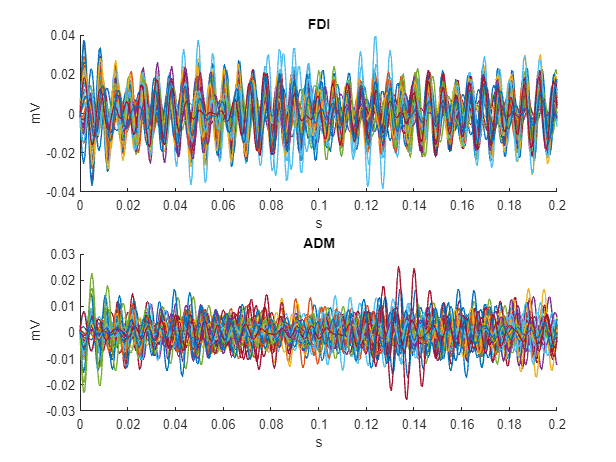

figure() % heterotopic ADM activation
for i = 1: length(t1_index) 
subplot(2,1,1)
hold on
plot(t, vibration_signal(:,1,t1_index(i)))
title(channels(1).title)
xlabel(x_units)
ylabel(channels(1).units)
xlim([0,0.2])
hold off

subplot(2,1,2)
hold on
plot(t, vibration_signal(:,2,t1_index(i)))
title(channels(2).title)
xlabel(x_units)
ylabel(channels(2).units)
xlim([0,0.2])
hold off
end

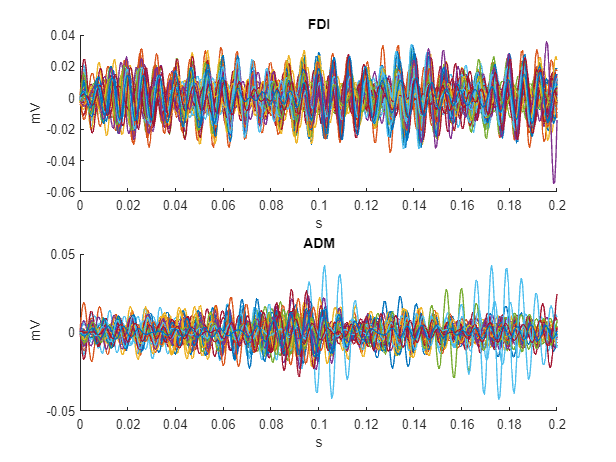


figure() % heterotopic FDI activation
for i = 1: length(t2_index) 
subplot(2,1,1)
hold on
plot(t, vibration_signal(:,1,t2_index(i)))
title(channels(1).title)
xlabel(x_units)
ylabel(channels(1).units)
xlim([0,0.2])
hold off

subplot(2,1,2)
hold on
plot(t, vibration_signal(:,2,t2_index(i)))
title(channels(2).title)
xlabel(x_units)
ylabel(channels(2).units)
xlim([0,0.2])
hold off
end

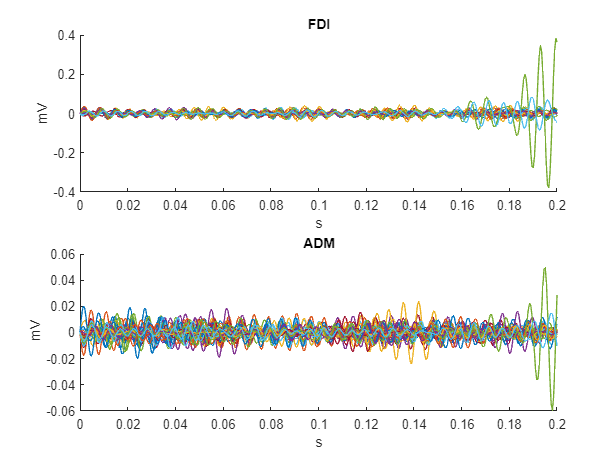


figure() % homotopic FDI activation
for i = 1: length(t3_index) 
subplot(2,1,1)
hold on
plot(t, vibration_signal(:,1,t3_index(i)))
title(channels(1).title)
xlabel(x_units)
ylabel(channels(1).units)
xlim([0,0.2])
hold off

subplot(2,1,2)
hold on
plot(t, vibration_signal(:,2,t3_index(i)))
title(channels(2).title)
xlabel(x_units)
ylabel(channels(2).units)
xlim([0,0.2])
hold off
end

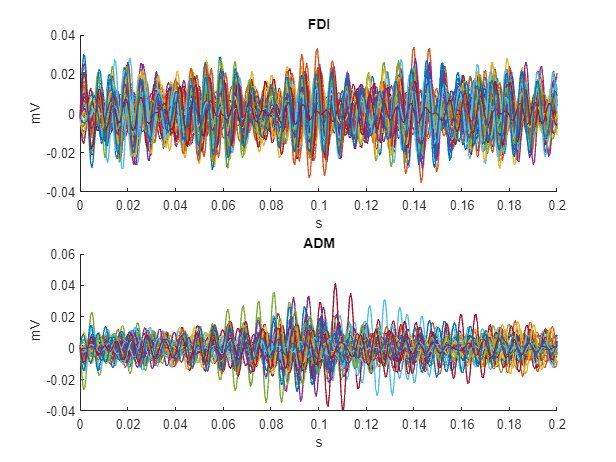


figure() % homotopic ADM activation
for i = 1: length(t4_index) 
subplot(2,1,1)
hold on
plot(t, vibration_signal(:,1,t4_index(i)))
title(channels(1).title)
xlabel(x_units)
ylabel(channels(1).units)
xlim([0,0.2])
hold off

subplot(2,1,2)
hold on
plot(t, vibration_signal(:,2,t4_index(i)))
title(channels(2).title)
xlabel(x_units)
ylabel(channels(2).units)
xlim([0,0.2])
hold off
end

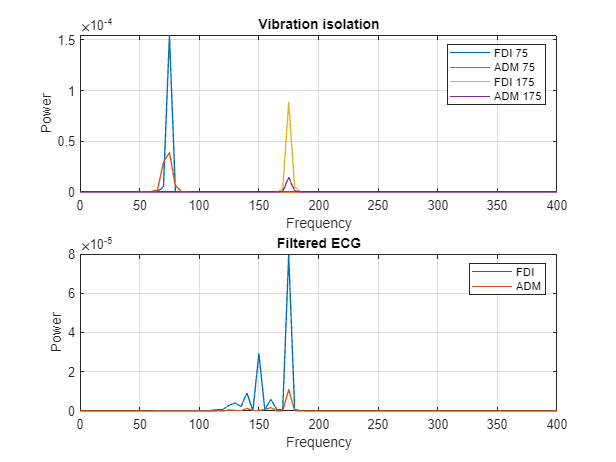

figure() % type 1 heterotopic FDI vibration

subplot(2,1,1)
plot(limited_f, ps_vibration75(:,1,18), limited_f, ps_vibration75(:,2,18), limited_f, ps_vibration175(:,1,18), limited_f, ps_vibration175(:,2,18))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI 75','ADM 75', 'FDI 175', 'ADM 175')
title('Vibration isolation')
grid("on")

subplot(2,1,2)
plot(limited_f, ps_vibration(:,1,18),limited_f, ps_vibration(:,2,18))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI','ADM')
title('Filtered ECG')
grid("on")

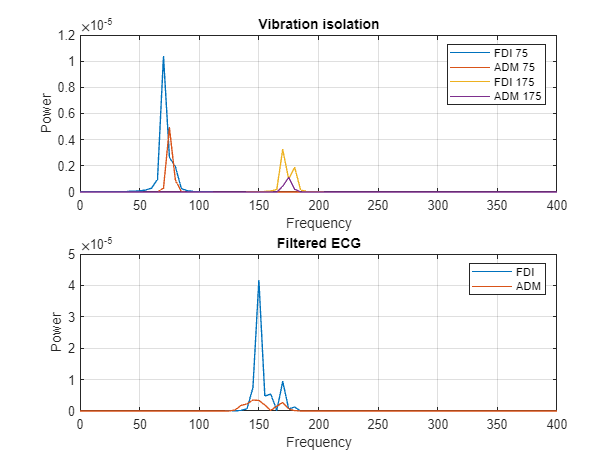


figure() % type 2 heterotopic ADM vibration

subplot(2,1,1)
plot(limited_f, ps_vibration75(:,1,28), limited_f, ps_vibration75(:,2,28), limited_f, ps_vibration175(:,1,28), limited_f, ps_vibration175(:,2,28))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI 75','ADM 75', 'FDI 175', 'ADM 175')
title('Vibration isolation')
grid("on")

subplot(2,1,2)
plot(limited_f, ps_vibration(:,1,28),limited_f, ps_vibration(:,2,28))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI','ADM')
title('Filtered ECG')
grid("on")

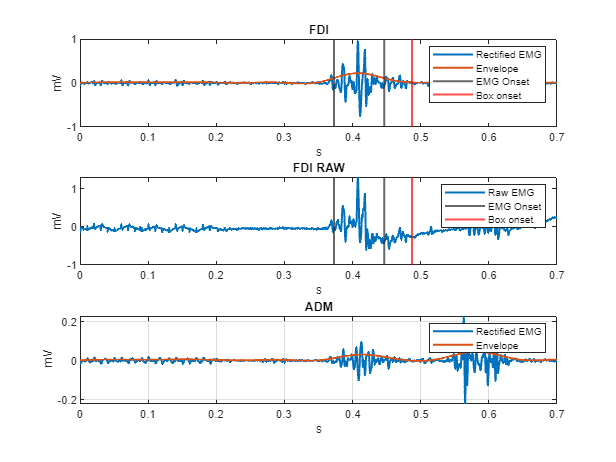

figure() % type 3 homotopic FDI vibration

subplot(3,1,1)
plot(t, filtered_signal(:,1,5), t, enveloped_signal(:,1,5), 'LineWidth', 1.5)
xline(emg_signal_onset_t(5,1),'LineWidth',1.5)
xline(emg_signal_end_t(5,1),'LineWidth',1.5)
xline(emg_signal_onset_t(5,3),'LineWidth',1.5,'Color','r')
legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
xlim([0,0.7])
title(channels(1).title)
xlabel(x_units)
ylabel(channels(1).units)

subplot(3,1,2)
plot(t,values(:,1,5), 'LineWidth', 1.5)
xline(emg_signal_onset_t(5,1),'LineWidth',1.5)
xline(emg_signal_end_t(5,1),'LineWidth',1.5)
xline(emg_signal_onset_t(5,3),'LineWidth',1.5,'Color','r')
legend('Raw EMG', 'EMG Onset', '', 'Box onset')
xlim([0,0.7])
title(channels(1).title + " RAW")
xlabel(x_units)
ylabel(channels(1).units)

subplot(3,1,3)
plot(t, filtered_signal(:,2,5), t, enveloped_signal(:,2,5), 'LineWidth', 1.5)
legend('Rectified EMG', 'Envelope')
xlim([0,0.7])
title(channels(2).title)
xlabel(x_units)
ylabel(channels(2).units)

grid("on")

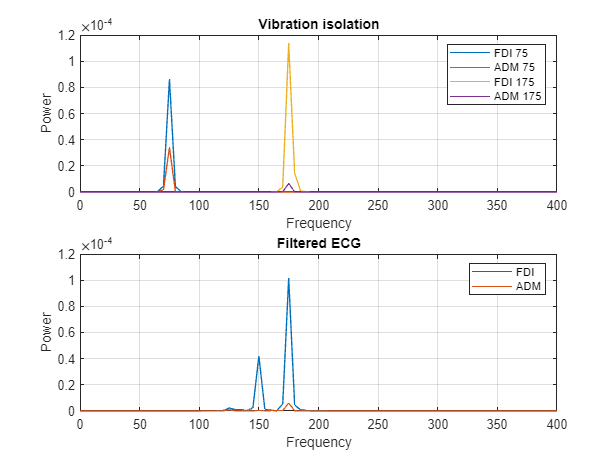

figure() % type 3 homotopic
% vibration in raw data -> TODO: spectrum, find fodamental frequency and
% band pass | only vibration is left
% not perfect rest on vibrator
% list input(vibration)-output(FDI ADM)-RT for each trial(t1,t2,t3,t4)
% limited_f = (0:vibration_sample_size-1)*vibration_sample_size;
subplot(2,1,1)
plot(limited_f, ps_vibration75(:,1,5), limited_f, ps_vibration75(:,2,5), limited_f, ps_vibration175(:,1,5), limited_f, ps_vibration175(:,2,5))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI 75','ADM 75', 'FDI 175', 'ADM 175')
title('Vibration isolation')
grid("on")

subplot(2,1,2)
plot(limited_f, ps_vibration(:,1,5),limited_f, ps_vibration(:,2,5))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI','ADM')
title('Filtered ECG')
grid("on")

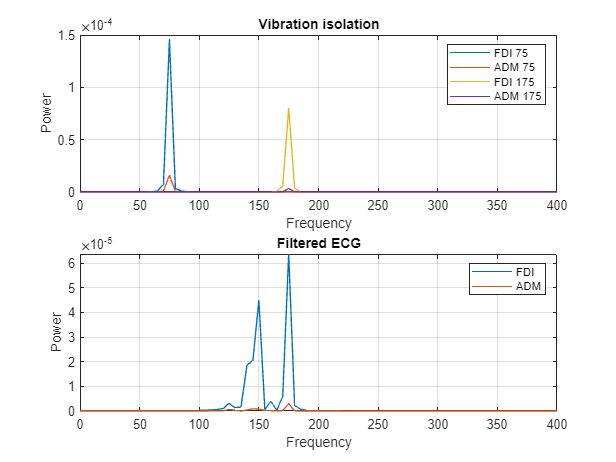

figure() % type 3 homotopic
subplot(2,1,1)
plot(limited_f, ps_vibration75(:,1,3), limited_f, ps_vibration75(:,2,3), limited_f, ps_vibration175(:,1,3), limited_f, ps_vibration175(:,2,3))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI 75','ADM 75', 'FDI 175', 'ADM 175')
title('Vibration isolation')
grid("on")

subplot(2,1,2)
plot(limited_f, ps_vibration(:,1,3),limited_f, ps_vibration(:,2,3))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI','ADM')
title('Filtered ECG')
grid("on")

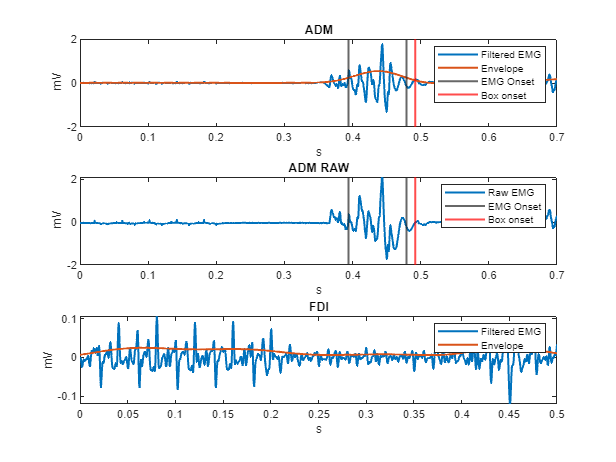

figure() % type 4 homotopic ADM vibration

subplot(3,1,1)
plot(t, filtered_signal(:,2,12), t, enveloped_signal(:,2,12), 'LineWidth', 1.5)
xline(emg_signal_onset_t(12,2),'LineWidth',1.5)
xline(emg_signal_end_t(12,2),'LineWidth',1.5)
xline(emg_signal_onset_t(12,3),'LineWidth',1.5,'Color','r')
legend('Filtered EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
xlim([0,0.7])
title(channels(2).title)
xlabel(x_units)
ylabel(channels(2).units)

subplot(3,1,2)
plot(t,values(:,2,12), 'LineWidth', 1.5)
xline(emg_signal_onset_t(12,2),'LineWidth',1.5)
xline(emg_signal_end_t(12,2),'LineWidth',1.5)
xline(emg_signal_onset_t(12,3),'LineWidth',1.5,'Color','r')
legend('Raw EMG', 'EMG Onset', '', 'Box onset')
xlim([0,0.7])
title(channels(2).title + " RAW")
xlabel(x_units)
ylabel(channels(2).units)

subplot(3,1,3)
plot(t, filtered_signal(:,1,12), t, enveloped_signal(:,1,12), 'LineWidth', 1.5)
legend('Filtered EMG', 'Envelope')
xlim([0,0.5])
title(channels(1).title)
xlabel(x_units)
ylabel(channels(1).units)

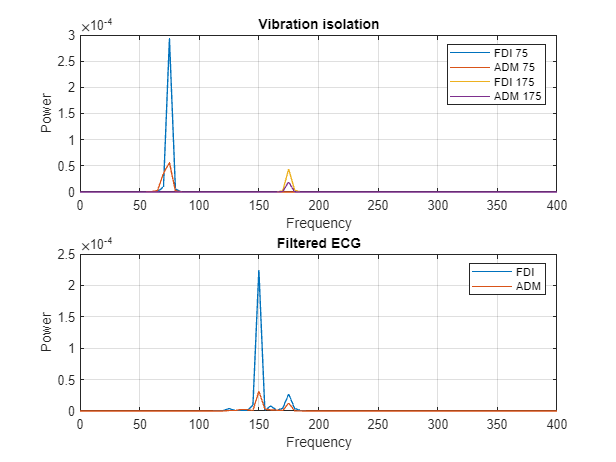


figure() % type 4 homotopic

subplot(2,1,1)
plot(limited_f, ps_vibration75(:,1,12), limited_f, ps_vibration75(:,2,12), limited_f, ps_vibration175(:,1,12), limited_f, ps_vibration175(:,2,12))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI 75','ADM 75', 'FDI 175', 'ADM 175')
title('Vibration isolation')
grid("on")

subplot(2,1,2)
plot(limited_f, ps_vibration(:,1,12),limited_f, ps_vibration(:,2,12))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI','ADM')
title('Filtered ECG')
grid("on")

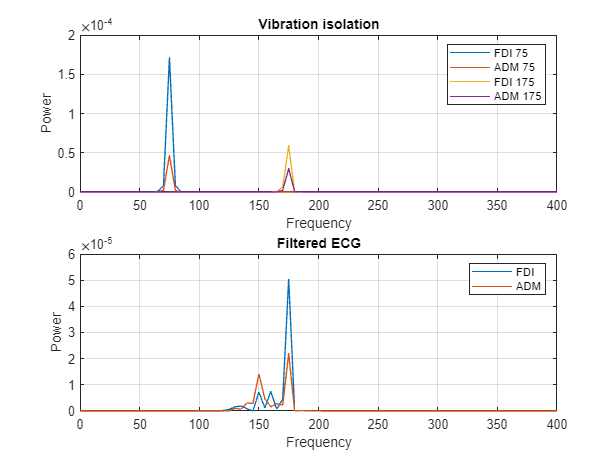

figure() % type 4 homotopic

subplot(2,1,1)
plot(limited_f, ps_vibration75(:,1,13), limited_f, ps_vibration75(:,2,13), limited_f, ps_vibration175(:,1,13), limited_f, ps_vibration175(:,2,13))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI 75','ADM 75', 'FDI 175', 'ADM 175')
title('Vibration isolation')
grid("on")

subplot(2,1,2)
plot(limited_f, ps_vibration(:,1,13),limited_f, ps_vibration(:,2,13))
xlim([0,400])
xlabel('Frequency')
ylabel('Power')
legend('FDI','ADM')
title('Filtered ECG')
grid("on")

% ratio on 175

# Plotting

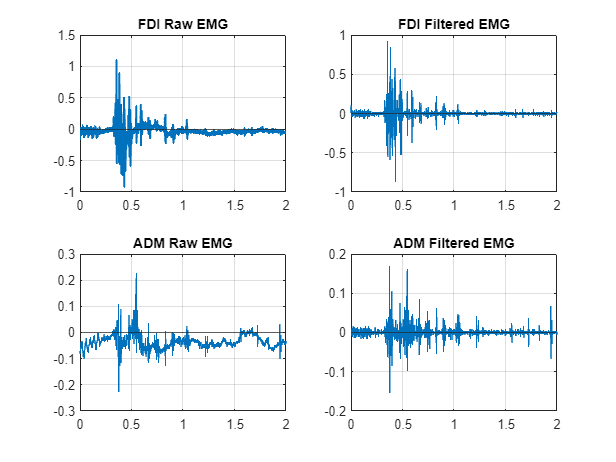

figure()

subplot(2,2,1)
xlabel(x_units)
ylabel(channels(1).units)
plot(t,values(:,1,2), 'LineWidth', 1.5)
yline(0)
title(channels(1).title + " Raw EMG")
grid("on")

subplot(2,2,3)
xlabel(x_units)
ylabel(channels(2).units)
plot(t,values(:,2,2))
yline(0)
title(channels(2).title + " Raw EMG")
grid("on")

subplot(2,2,2)
xlabel(x_units)
ylabel(channels(1).units)
plot(t,filtered_signal(:,1,2))
yline(0)
title(channels(1).title + " Filtered EMG")
grid("on")

subplot(2,2,4)
xlabel(x_units)
ylabel(channels(2).units)
plot(t,filtered_signal(:,2,2))
yline(0)
title(channels(2).title + " Filtered EMG")
grid("on")

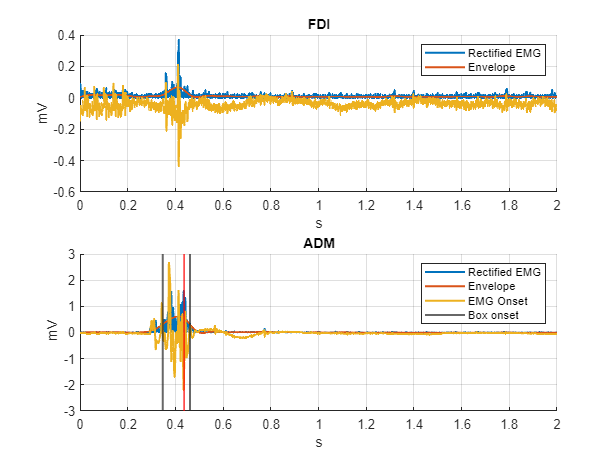

% type 1 % vibration looks strange
figure()

for i = 1:length(values(1,1:2,1)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,4), t, enveloped_signal(:,i,4), t, values(:,i,4), 'LineWidth', 1.5)
    if emg_signal_onset_t(4,i) ~= -1
        xline(emg_signal_onset_t(4,i),'LineWidth',1.5)
        xline(emg_signal_end_t(4,i),'LineWidth',1.5)
        if emg_signal_onset_t(4,3) ~= -1
            xline(emg_signal_onset_t(4,3),'LineWidth',1.4,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end % vibration fdi heterotropic

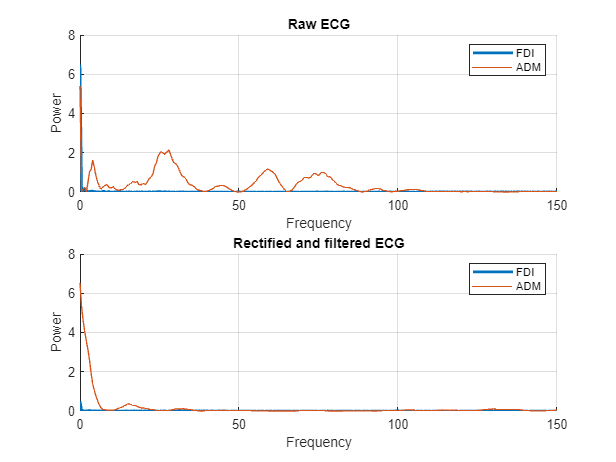

figure()
subplot(2,1,1)
hold on
plot(f,power_spectrum_raw(:,1,4),'LineWidth',2)
plot(f, power_spectrum_raw(:,2,4))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')
grid("on")

subplot(2,1,2)
hold on
plot(f,power_spectrum(:,1,4),'LineWidth',2)
plot(f, power_spectrum(:,2,4))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')
grid("on")

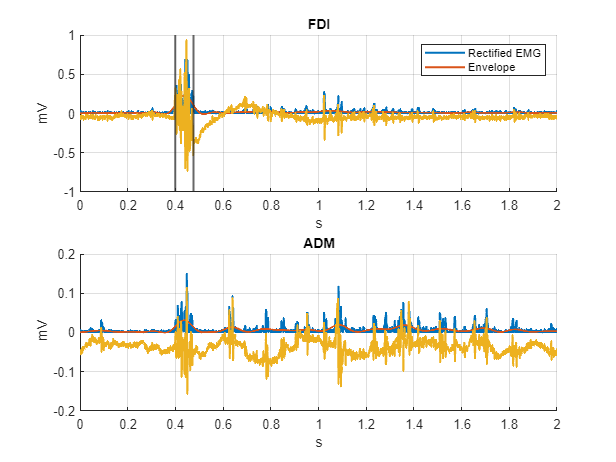

%type 2 % can't see the vibration here. What to do?
figure()

for i = 1:length(values(1,1:2,8)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,8), t, enveloped_signal(:,i,8), t, values(:,i,8), 'LineWidth', 1.5)
    if emg_signal_onset_t(8,i) ~= -1
        xline(emg_signal_onset_t(8,i),'LineWidth',1.5)
        xline(emg_signal_end_t(8,i),'LineWidth',1.5)
        if emg_signal_onset_t(8,3) ~= -1
            xline(emg_signal_onset_t(8,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        % legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

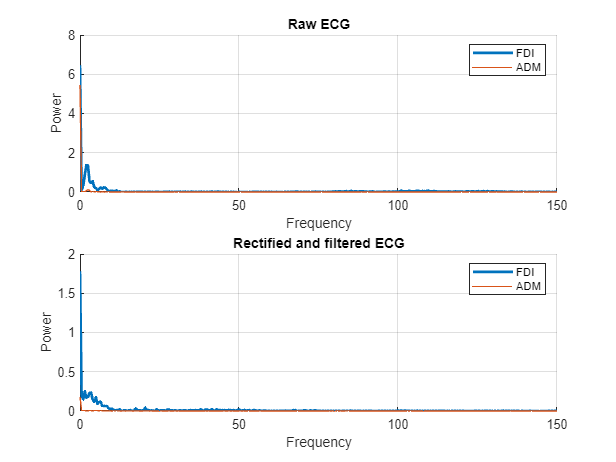

figure()
subplot(2,1,1)
hold on
plot(f,power_spectrum_raw(:,1,8),'LineWidth',2)
plot(f, power_spectrum_raw(:,2,8))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')
grid("on")

subplot(2,1,2)
hold on
plot(f,power_spectrum(:,1,8),'LineWidth',2)
plot(f, power_spectrum(:,2,8))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')
grid("on")

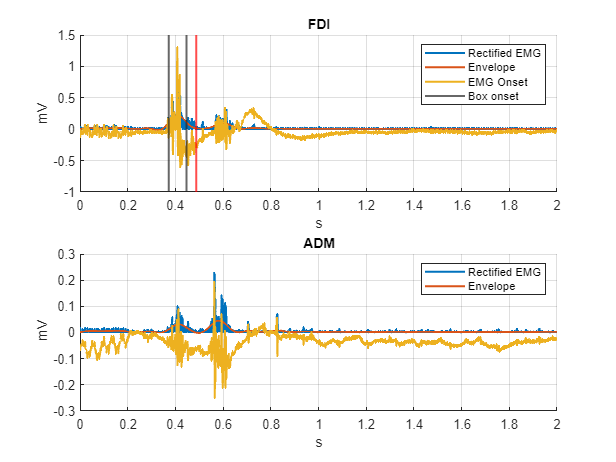

% type 3

figure()
for i = 1:length(values(1,1:2,3)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,5), t, enveloped_signal(:,i,5),t,values(:,i,5), 'LineWidth', 1.5)
    if emg_signal_onset_t(5,i) ~= -1
        xline(emg_signal_onset_t(5,i),'LineWidth',1.5)
        xline(emg_signal_end_t(5,i),'LineWidth',1.5)
        if emg_signal_onset_t(5,3) ~= -1
            xline(emg_signal_onset_t(5,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

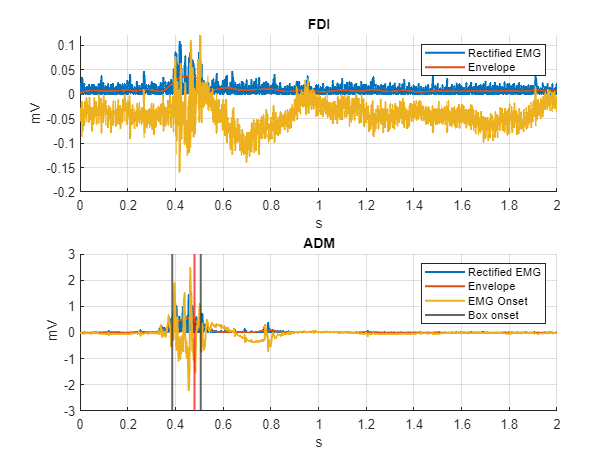

% type 4
figure()
for i = 1:length(values(1,1:2,5)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,6), t, enveloped_signal(:,i,6), t, values(:,i,6), 'LineWidth', 1.5)
    if emg_signal_onset_t(6,i) ~= -1
        xline(emg_signal_onset_t(6,i),'LineWidth',1.5)
        xline(emg_signal_end_t(6,i),'LineWidth',1.5)
        if emg_signal_onset_t(6,3) ~= -1
            xline(emg_signal_onset_t(6,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

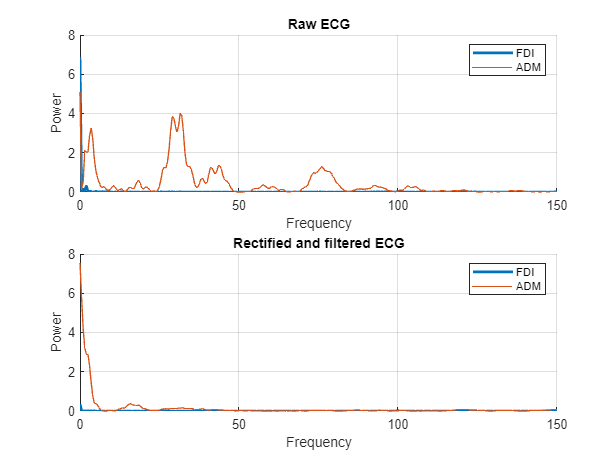

figure()
subplot(2,1,1)
hold on
plot(f,power_spectrum_raw(:,1,6),'LineWidth',2)
plot(f, power_spectrum_raw(:,2,6))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')
grid("on")

subplot(2,1,2)
hold on
plot(f,power_spectrum(:,1,6),'LineWidth',2)
plot(f, power_spectrum(:,2,6))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')
grid("on")

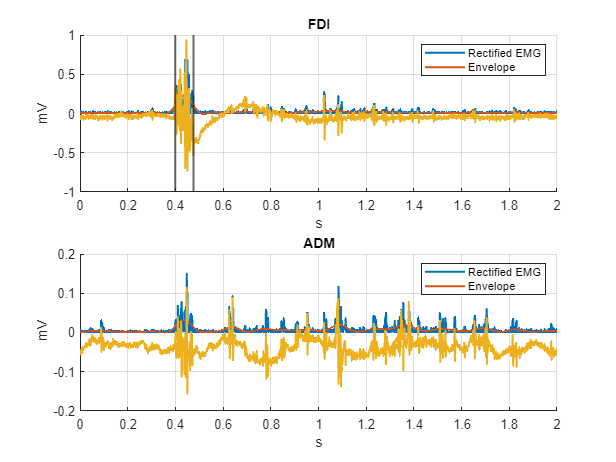

% 99 case
figure()

for i = 1:length(values(1,1:2,8)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,8), t, enveloped_signal(:,i,8),t,values(:,i,8), 'LineWidth', 1.5)
    if emg_signal_onset_t(8,i) ~= -1
        xline(emg_signal_onset_t(8,i),'LineWidth',1.5)
        xline(emg_signal_end_t(8,i),'LineWidth',1.5)
        if emg_signal_onset_t(8,3) ~= -1
            xline(emg_signal_onset_t(8,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

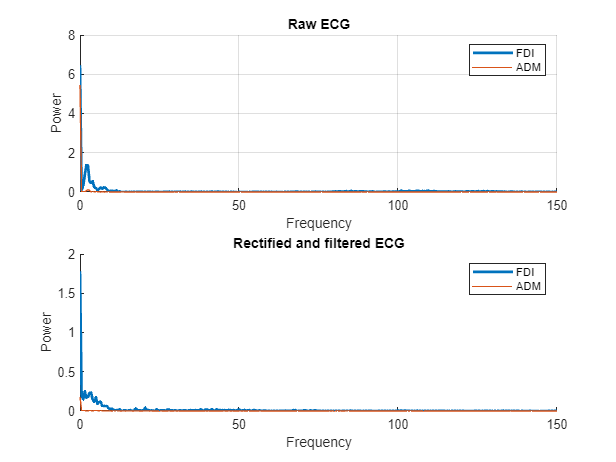

figure()
subplot(2,1,1)
hold on
plot(f,power_spectrum_raw(:,1,8),'LineWidth',2)
plot(f, power_spectrum_raw(:,2,8))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')
grid("on")

subplot(2,1,2)
hold on
plot(f,power_spectrum(:,1,8),'LineWidth',2)
plot(f, power_spectrum(:,2,8))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')

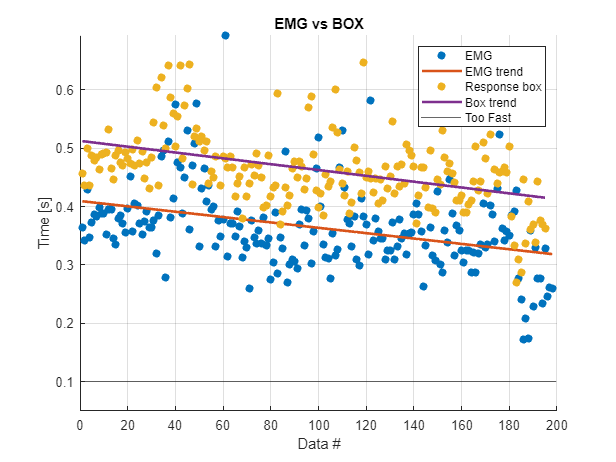

% Reaction times comparison plot

figure()

x_emg = linspace(1,length(reaction_time_emg),length(reaction_time_emg));
x_box = linspace(1,length(reaction_time_box),length(reaction_time_box));

p_emg = polyfit(x_emg, reaction_time_emg, 1);
fit_emg = polyval(p_emg, x_emg);

p_box = polyfit(x_box, reaction_time_box, 1);
fit_box = polyval(p_box, x_box);

hold on
scatter(x_emg, reaction_time_emg, 'filled')
plot(fit_emg, 'LineWidth', 2)
scatter(x_box, reaction_time_box, 'filled')
plot(fit_box, 'LineWidth', 2)
yline(0.1)
ylim([0.05,max(reaction_time_emg)])
hold off
legend('EMG', 'EMG trend', 'Response box', 'Box trend', 'Too Fast')
xlabel("Data #")
ylabel("Time [s]")
title("EMG vs BOX")
grid('on')

# Summary statistics

tests = {t1_index; t2_index; t3_index; t4_index};

for i = 1:length(tests(:,1))
    temp = cell2mat(tests(i));
    disp("Test type: " + i)

    switch(detected(temp(1)))
        case 1
            disp("Detected FDI movement")
        case 2
            disp("Detected ADM movement")
        case 3
            disp("Detected both FDI and ADM movement")
        case 0
            disp("No movement detected")
    end

    disp("---------------------------------")
    disp("Max: " + max(reaction_time_emg(temp)))
    disp("Min: " + min(reaction_time_emg(temp))) 
    disp("Mean: " + mean(reaction_time_emg(temp)))
    disp("Median: " + median(reaction_time_emg(temp)))
    disp("Standard deviation: " + std(reaction_time_emg(temp)))
    disp("---------------------------------")
end

Test type: 1


Detected ADM movement


---------------------------------


Max: 0.57564


Min: 0.24106


Mean: 0.35819


Median: 0.34334


Standard deviation: 0.079512


---------------------------------


Test type: 2


Detected FDI movement


---------------------------------


Max: 0.51063


Min: 0.20905


Mean: 0.36503


Median: 0.36959


Standard deviation: 0.064424


---------------------------------


Test type: 3


Detected FDI movement


---------------------------------


Max: 0.49462


Min: 0.17254


Mean: 0.33816


Median: 0.33858


Standard deviation: 0.054966


---------------------------------


Test type: 4


Detected ADM movement


---------------------------------


Max: 0.69367


Min: 0.27607


Mean: 0.39298


Median: 0.38385


Standard deviation: 0.072255


---------------------------------
